clear;
clc;

## 第一部分 常量定义

定义等待计算的时间区域$(t_{0},t_{\rm end})$和空间区域$({\bf\it x}_{0},{\bf\it x}_{\rm end})$.

t_0=0;
t_end=1;
x_0=0;
x_end=1;
%计算区间长度
timeLength=t_end-t_0;
xLength=x_end-x_0;

定义时间方向的总步数K,空间方向的总步数J

K=100;
J=100;

定义均匀的计算步长

tau=timeLength/K;
h=xLength/J;

定义初始时刻的边界条件

f=@(x)exp(-x.^2);

定义数值解的离散储存矩阵$u(x,t),x\in [0,1],t\in[0,1]$.

u=zeros(J+1,K+1);

## 第二部分 循环计算

首先将初始时刻的函数数值赋予储存矩阵

%{
为了程序和公式中的步进变元保持一致,
这里定义j_c作为循环变元(_c是C++数组的意思).
但是用j=j_c+1作为数组计算变量,
并且定义一个时间方向的初始步长变量k0=1.
%}
k0=1;
for j_c=0:J
    j=j_c+1;
    %主要循环计算部分,之后的程序不再说明
    u(j,k0)=f(j_c*h);
end

然后用迎风格式


$$r:=\frac{a\tau}{h},u_{j}^{k+1}=(1-r)u_{j}^{k}+ru_{j-1}^{k}$$


进行计算,其中步数$J=1:J,K=0:K-1$.

考虑到传输方程的解如果是连续的,那么当空间位置固定时,$u(x_{j},t_{k})\approx u(x_{j},t_{k+1})$.因此计算出${\it\bf u}^{k+1}$后,将$u_{1}^{k+1}$的值赋予$u_{0}^{k+1}$,作为近似的初始位移初值(尽管这并不必要)

a=1;
r=a*tau/h;
for k_c=0:K-1
    k=k_c+1;
    for j_c=1:J
        j=j_c+1;
        u(j,k+1)=(1-r)*u(j,k)+r*u(j-1,k);
    end
    u(1,k+1)=u(2,k+1);
end

定义精确解和其数值储存矩阵

%方便起见,定义ESM:=exact solution storage matrix
u_ES=@(x,t)f(x-a*t);
u_ESM=zeros(J+1,K+1);
for k_c=0:K
    k=k_c+1;
    for j_c=0:J
        j=j_c+1;
        u_ESM(j,k)=u_ES(j*h,k*tau);
    end
end

定义误差矩阵$M_{\rm error}$,并计算$\max (i,j)[M_{\rm error}(i,j)]$作为误差界.

j1=2;
k1=2;
errorMatrix=u_ESM(j1:(end-1),k1:(end-1))-u(j1:(end-1),k1:(end-1));
error_max=max(abs(errorMatrix),[],'all');
error_ave=mean(mean(errorMatrix));
%dispwithname是一个能够同时输出多个变量数值和其名称的函数
quickdisp(r,error_max,error_ave)

r= 1
error_max= 0.61726
error_ave= -0.068086


## 第三部分 结果分析

绘制精确解与数值解的空间图像

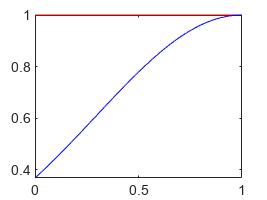

%mesh(tau*(0:K),h*(0:J),u_ESM)
%mesh(tau*(0:K),h*(0:J),u)
for k=0:K
    axis([0,1,-1,1])
    plot(h*(0:J),u(:,k+1),"red");
    hold on
    plot(h*(0:J),u_ESM(:,k+1),"blue");
    hold off
    pause(0.01)
end

因为计算区域有限,所以数值解会将初始时刻的$0$值不断向前输送,而精确解将全域上的结果输送到计算区域.

因此,在波前进的方向,数值解与精确解一致,但在波的后方,数值解只固定在了初始时刻的值.

但是由于波后方的函数并不在域${\it\Omega}=[0,1]\times [0,1]$内,因此实际上,可以重新定义$u({\it\bf x},0)=\left\lbrace \begin{array}{cl}
 f({\it\bf x}),& {\it\bf x}\geq 0,\\
 f({\it\bf 0}),& {\it\bf x}<0.
\end{array}\right.$

现在用新的函数计算误差

%在末尾我定义了newf,用分段函数的形式.
u_ES=@(x,t)newf(x-a*t);
for k_c=0:K
    k=k_c+1;
    for j_c=0:J
        j=j_c+1;
        u_ESM(j,k)=u_ES(j*h,k*tau);
    end
end
errorMatrix=u_ESM-u;
newError_max=max(abs(errorMatrix),[],'all');
quickdisp(newError_max)

newError_max= 2.2204e-16


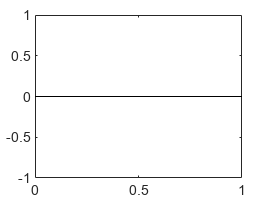

for k=0:K
    axis([0,1,-newError_max,newError_max])
    plot(h*(0:J),u_ESM(:,k+1)-u(:,k+1),"black");
    pause(0.1)
end

结果很好.

以下是函数定义部分.

function quickdisp(varargin)
    for i=1:nargin
      disp([inputname(i) '= ' num2str(varargin{i})])
    end
end
function value=newf(x)
    f=@(x)exp(-x.^2);
    if(x>=0)
        value=f(x);
    else
        value=f(0);
    end
end